## Seven minute *hctsa*

### 0—Adding hctsa to path

Go to directory where *hctsa* is installed and run:

startup

This should add all the paths needed for *hctsa*. You can then return to this directory.

### 1—Prepare the dataset

Let's see how we structure a time-series dataset in preparation for an *hctsa* analysis. We create an input file. For this dataset:

load('INP_Bonn_EEG.mat')

This file includes:

- `labels`, a 500 x 1 cell of strings that uniquely identify each time series,

- `timeSeriesData`, a 500 x 1 cell containing vectors of time-series data, and

- `keywords`, a 500 x 1 cell of strings (class labels)

### 2—Initialize

Now that we have our input file, we can initialize our *hctsa* data file that will contain all the results of our feature extraction and other processing we might want to do to it.

We could do this with the full *hctsa* feature set as simply `TS_Init('INP_Bonn_EEG.mat','hctsa')`, but computing the results of the full *hctsa* feature set will take some hours to complete for this dataset… :-/

So today we'll do it with a reduced feature set, the fast subset of 22 features, *catch22*, as:

tellMeEverything = false; % turn on for the full experience

Returning a table with metadata for 500 time series.
Returning a table with metadata for 22 master operations.
Returning a table with metadata for 22 operations.
Successfully initialized file 'HCTSA.mat' with 500 time series, 22 master operations, and 22 operations.


TS_Init('INP_Bonn_EEG.mat','catch22',tellMeEverything)
% catch22 + mean + std
% TS_Init('INP_Bonn_EEG.mat','catch24',tellMeEverything)
% full hctsa feature set
% TS_Init('INP_Bonn_EEG.mat','hctsa',tellMeEverything)

This generates an `HCTSA.mat` file. We can select it to see what's inside. For the *catch22* feature set, we will have:

- `TS_DataMat`, a 500 (time series x 22 (features) matrix of calculated features (empty for now),

- `TimeSeries`, a 500-row table with information about time series, and

- `Operations`, a 22-row table with information about all of the features.

### 3—Extract features

We can fill in all the blanks in `TS_DataMat` with actual computed features for each combination of time series and features as:

TS_Compute(false);

Loading data from HCTSA.mat... Done.
Computations will be performed serially without parallelization.
[17-Jul-2023 16:51:35]: Extracting 22 features from each of 500 time series.
|::::::::::::::::::::::::::::::::::::::::|
Calculations complete in a total of 21.6 seconds.
Saving all results to HCTSA.mat... Saved in 8ms.


### 4—Process the Results

We can next tell *hctsa* how to use information in the `keywords` part of our input file to label the classes in the dataset. In this case it's straightforward since we just have a single unique label for each class, so we can just run:

TS_LabelGroups();

Retrieving data from HCTSA.mat by default.
Loading data from HCTSA.mat... Done.
No keywords assigned for labeling. Attempting to use unique keywords from data...
Shall I use the following 5 keywords: 'epileptogenic', 'eyesClosed', 'eyesOpen', 'hippocampus', 'seizure'?
Group labeling complete in 48ms.
We found data for 5 labeled classes:
epileptogenic -- 100 matches (/500)
eyesClosed -- 100 matches (/500)
eyesOpen -- 100 matches (/500)
hippocampus -- 100 matches (/500)
seizure -- 100 matches (/500)
Saving group labeling back to HCTSA.mat... Saved.


We can take a peek at some example time series from each class, as:

Plotting from 5 groups of time series from file.
Plotting 50 (/500) time series from 5 classes


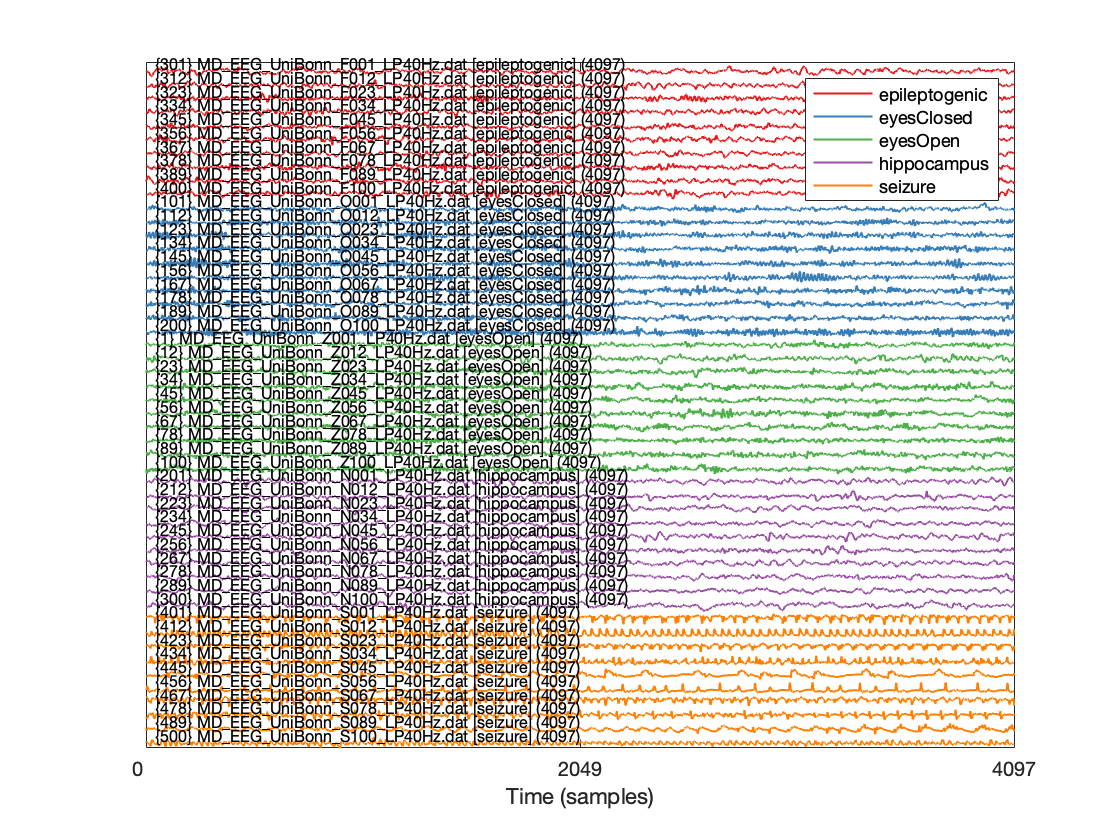

TS_PlotTimeSeries()

And we can filer out features with many missing values, and normalize them to a common scale as:

TS_Normalize();

Using the mixed sigmoidal transform: 'mixedSigmoid'
Removing time series with more than 30.00% special-valued outputs
Removing operations with more than 0.00% special-valued outputs
Loading data from HCTSA.mat... Done.

There are 0 special values in the data matrix.
(pre-filtering): Time series vary from 100.00--100.00% good values
(pre-filtering): Features vary from 100.00--100.00% good values
All 500 time series have greater than 70.00% good values. Keeping them all.
All 22 operations have greater than 100.00% good values. Keeping them all.
No operations had near-constant outputs on the dataset

(post-filtering): No special-valued entries in the 500x22 data matrix!

Normalizing a 500 x 22 object. Please be patient...
Normalized! The data matrix contains 0 special-valued elements.
No special-valued entries in the 500x22 data matrix!
Saving the trimmed, normalized data to HCTSA_N.mat... Done.


This saves the result in a new file, `HCTSA_N.mat`

### 5—Visualize/Play/Analyze!

We can play with a quick low-dimensional representation of the dataset in the feature space as:

Loading data from HCTSA_N.mat... Done.
Calculating 2-dimensional principal components of the 500 x 22 data matrix...
---Done.


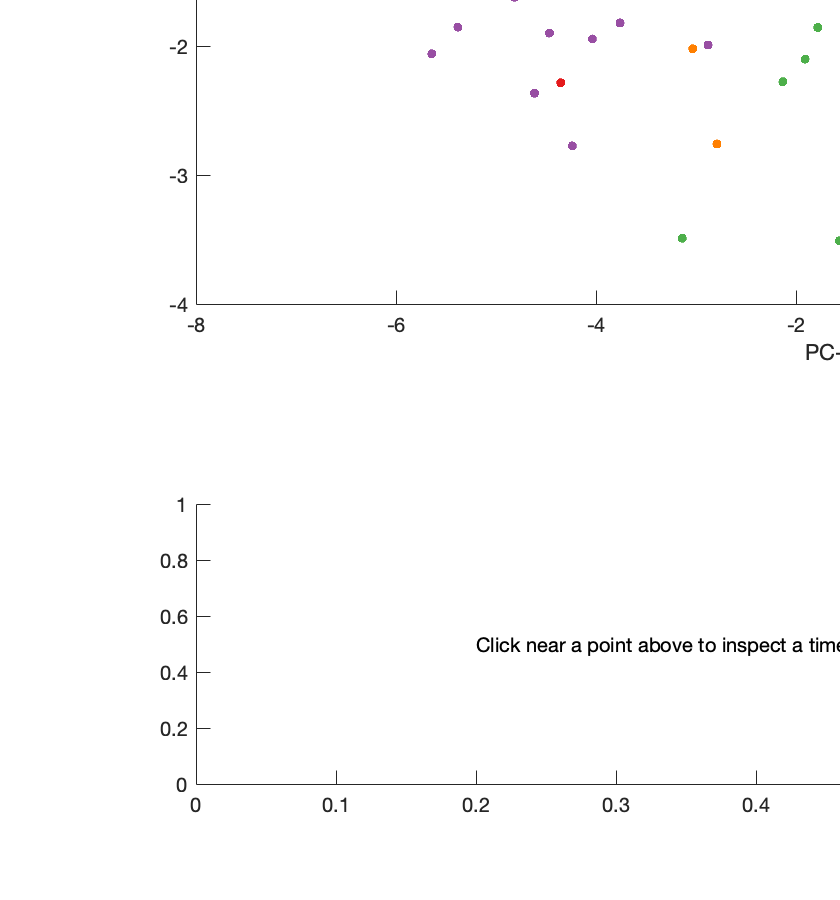

TS_LowDimInspect('norm','pca') % must be run in commandline for interactive window

Look at the clustered feature matrix?

First reorder rows (by euclidean distances) and columns (by correlation distance). Information is saved back into `HCTSA_N.mat`

TS_Cluster()

Let's look at the time series x feature matrix as a heatmap. Zoom in to see structure!

TS_PlotDataMatrix()

Let's make the groups easier to see by coloring them on different color scales:

TS_PlotDataMatrix('colorGroups',true)

We can also reorder by group if we want:

TS_PlotDataMatrix('colorGroups',true,'groupReorder',true)

### Classification

#### Default behavior

We can quickly get a sense for how accurately we can classify the time series in the 22-dimensional feature space:

TS_Classify()

#### Modifying the classifier

Try again with an radial basis function SVM classifier:

cfnParams = GiveMeDefaultClassificationParams('norm');
cfnParams.whatClassifier = 'svm-rbf';
TS_Classify('norm',cfnParams)

### Understanding the best features

What are the best features?

TS_TopFeatures('norm','classification',struct(),'numTopFeatures',12,'numFeaturesDistr',12)

### Relabeling the dataset

What about for a two-class subset?

TS_LabelGroups('norm',{'eyesOpen','seizure'})
annotateParams = struct('n',0,'textAnnotation','none','userInput',false);
TS_PlotLowDim('norm','pca',true,annotateParams)

Can you classify similarly well in a lower-dimensional PCA space?

TS_ClassifyLowDim('norm')

TS_LabelGroups('norm',{'epileptogenic','hippocampus'})
TS_TopFeatures('norm','ttest',[],'numNulls',10)

### **Probing specific features**

We want to understand individual features (run in commandline for interactive)

doInteractive = true;
myFavoriteFeatureID = 20;
TS_FeatureSummary(myFavoriteFeatureID,'raw',true,doInteractive)

### Find similar matches (in the feature space) to a given time series of interest:

TS_LabelGroups('norm')
timeSeriesID = 30;
TS_SimSearch(timeSeriesID,'ts')